# t_averageTSeries

Average the time series scans using sample data set [erniePRF](erniePRF)

Dependencies: Remote Data Toolbox Freesurfer Paths

% This tutorial is part of a sequence. Run 
%   t_initAnatomyFromFreesurfer
%   t_meshFromFreesurfer *optional
%   t_initVistaSession
%   t_alignInplaneToVolume *optional
%   t_installSegmentation  *optional
%   t_sliceTiming
%   t_motionCorrection
% prior to running this tutorial. 
%
% Summary
% - Average the time series scans and record the results in 'dataTYPES'
% 
% Tested 09/18/2016 - MATLAB R2015a, Mac OS 10.11.6 (Silvia Choi's computer)  
%
%  See also: t_initAnatomyFromFreesurfer t_meshesFromFreesurfer
%  t_initVistaSession t_alignInplaneToVolume t_installSegmentation
%  t_sliceTiming t_motionCorrection
%
%  Winawer lab (NYU)

## Organize functional data

% Find ernie PRF session in scratch directory
erniePathTemp      = fullfile(vistaRootPath, 'local', 'scratch', 'erniePRF');

if ~exist(erniePathTemp, 'dir')
    help(mfilename)
    error('Please run  pre-requisite tutorials')
end

% Navigate
cd(erniePathTemp);

## Average scans with the same stimulus

% Open a hidden view
vw = initHiddenInplane(); % to use the GUI (Graphical User Interface): vw = mrVista;

Initializing HIDDEN Inplane view
[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [80.000,104.000,12.000] pix.



% We will use the motion compensated data set called 'MotionComp' obatined
% from t_motionCorrection for averaging
vw = viewSet(vw, 'Current DataTYPE', 'MotionComp');

% Average the scans
if  any(strcmpi({dataTYPES.name}, 'Averages'))
    % Check whether Averages dataTYPE already exists. If so, skip this step.
    warning('Averaging has already been done on this data set. Skipping.')
else
    % Do it
    vw = averageTSeries(vw, 1:viewGet(vw, 'num scans'), 'Averages');
end

Initializing HIDDEN Inplane view
[niftiCheckQto] NIFTI header origin is at or outside the image volume.
[niftiCheckQto] Origin to the image center [80.000,104.000,12.000] pix.
Creating data type Averages
Made directory /Users/jonathanwinawer/matlab/toolboxes/vistasoft/local/scratch/erniePRF/Inplane/Averages
Updated dataTYPES variable in mrSESSION.mat.
Created directory /Users/jonathanwinawer/matlab/toolboxes/vistasoft/local/scratch/erniePRF/Inplane/Averages/TSeries
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
Averaged tSeries saved with annotation: Average of MotionComp scans: 1  2  3
Data are saved in Averages data type

Done Averaging tSeries.



% Check your Workspace. 'dataTYPES' should now be 1x5 struct array.
disp(size(dataTYPES))

     1     5




% Note also that the first 4 data types - Original, Timed,
% BwScansMotionComp, MotionComp - all have 3 scans. The Averages datatype
% has only one scan. 
vw = viewSet(vw, 'current data type', 'Timed');
disp(viewGet(vw, 'num scans'))

     3



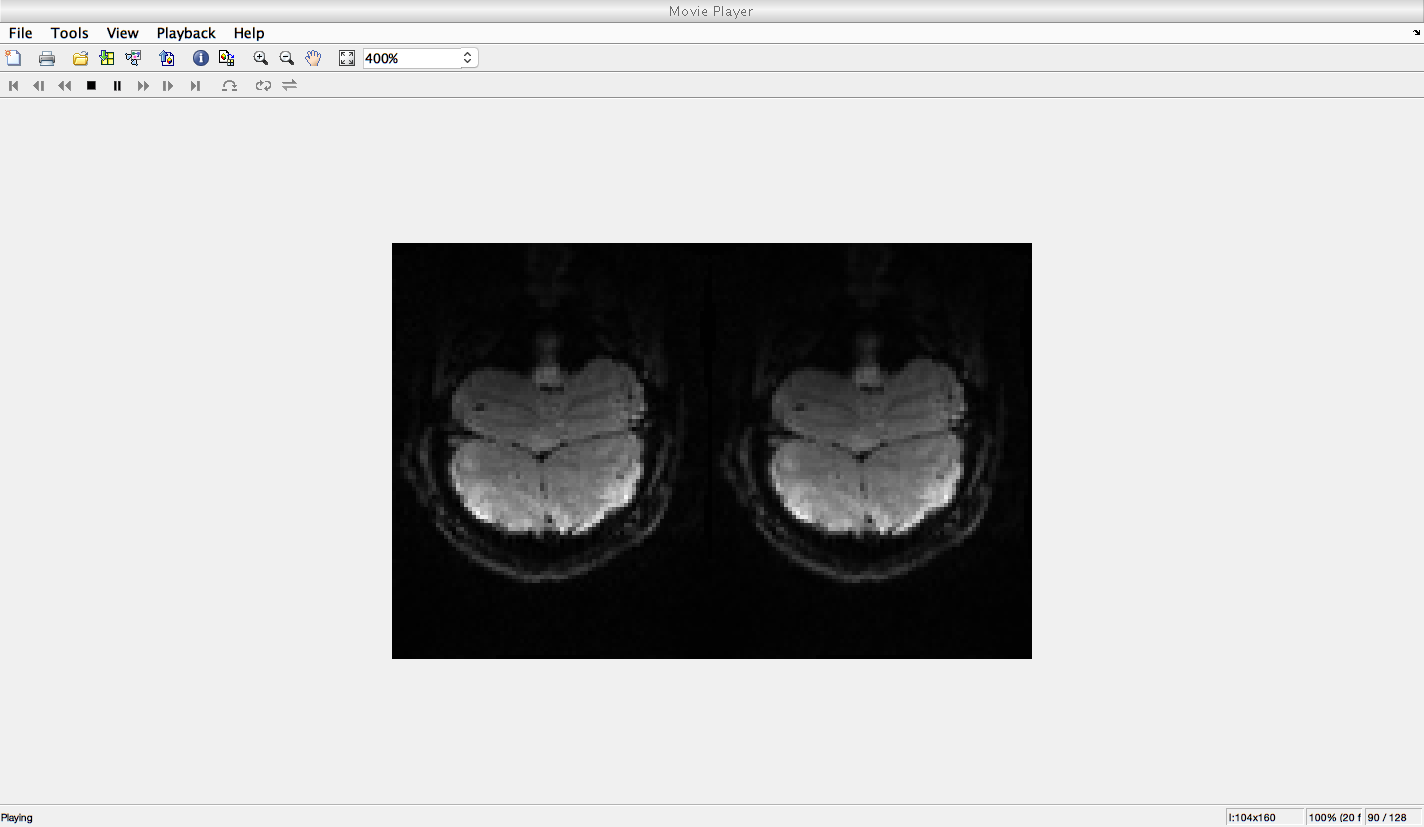


vw = viewSet(vw, 'current data type', 'Averages');

disp(viewGet(vw, 'num scans'))

     1



## Visualization

% Let's look at a single slice and compute the signal to noise ratio before
% and after averaging
whichSlice = round(viewGet(vw, 'num slices')/2); 

vw = viewSet(vw, 'Current DataTYPE', 'MotionComp');
vw = viewSet(vw, 'Current Scan', 1);
[~, nii]  = loadtSeries(vw, 1);

[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


tSeries.motionComp = niftiGet(nii, 'data');

snr.motionComp = mean(tSeries.motionComp,4)./std(tSeries.motionComp,[],4);

vw = viewSet(vw, 'Current DataTYPE', 'Averages');
vw = viewSet(vw, 'Current Scan', 1);
[~, nii]  = loadtSeries(vw, 1);

[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


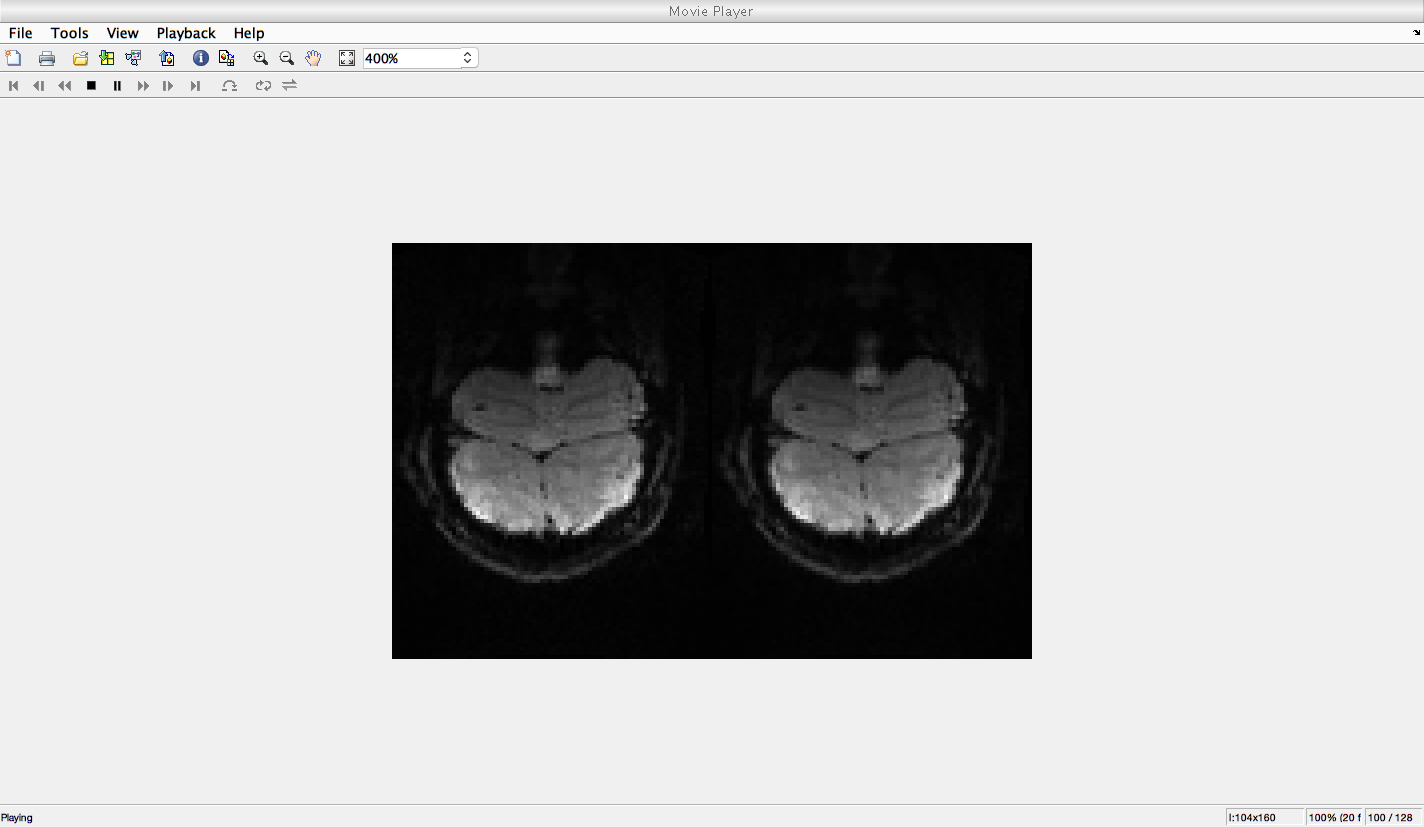

tSeries.average = niftiGet(nii, 'data');
snr.average = mean(tSeries.average,4)./std(tSeries.average,[],4);

fH = mrvNewGraphWin('Signal to noise ratio (mean divided by std)', 'wide');
subplot(1,3,1)
imagesc(snr.motionComp(:,:,whichSlice), [0 180]); axis image; colorbar
title('Signal to Noise Ratio of Unaveraged Data')

subplot(1,3,2)
imagesc(snr.average(:,:,whichSlice), [0 180]); axis image; colorbar

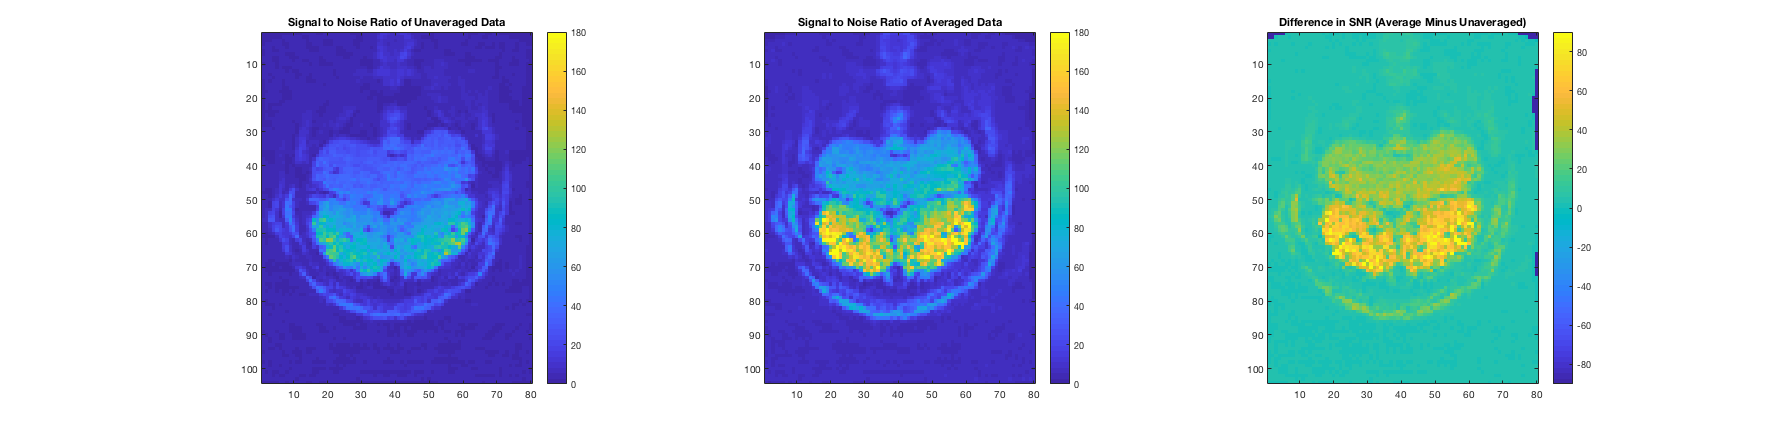

title('Signal to Noise Ratio of Averaged Data')

subplot(1,3,3)
imagesc(snr.average(:,:,whichSlice) - snr.motionComp(:,:,whichSlice), [-90 90]); 
axis image; colorbar
title('Difference in SNR (Average Minus Unaveraged)')


% Note that within the brain area, the signal to noise ratio is much higher
% in the average data than in the original data. 
%

## Visualization 2: time series

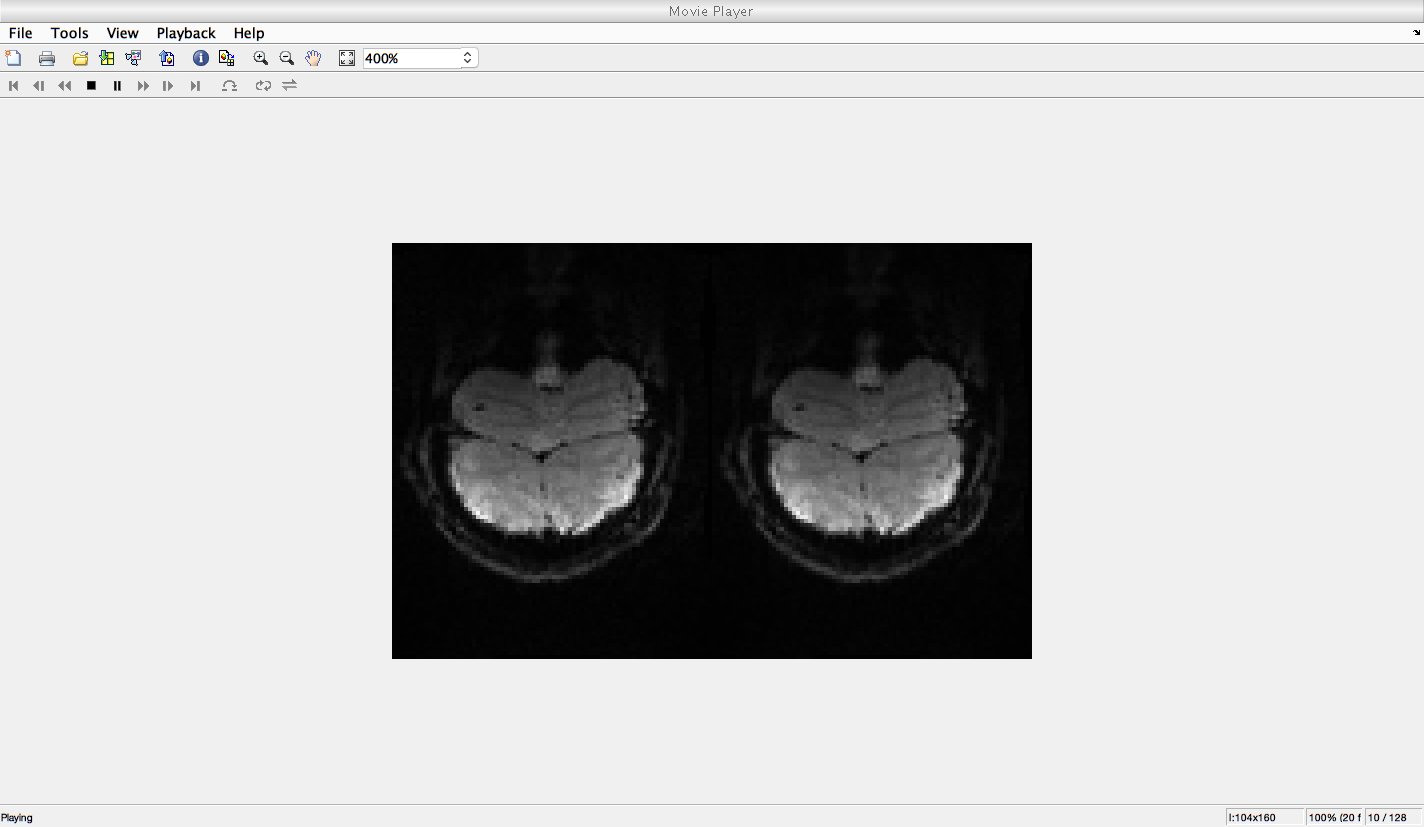

[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.
[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


vw = newROI(vw, 'good voxel', [], [], [119; 107; 12;]);
vw = viewSet(vw, 'Current Data TYPE', 'MotionComp');
fH(2) = mrvNewGraphWin();
plotMeanTSeries(vw,1:3);

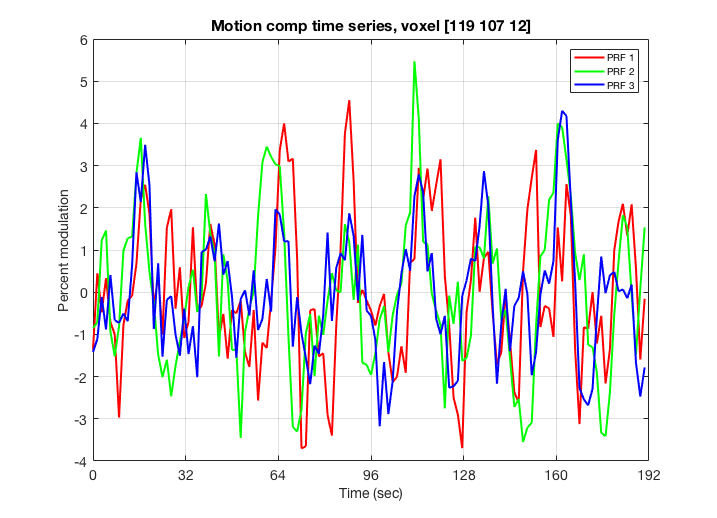

title('Motion comp time series, voxel [119 107 12]')


vw = viewSet(vw, 'Current Data TYPE', 'Averages');
fH(3) = mrvNewGraphWin();
plotMeanTSeries(vw,1);

[niftiApplyXform:] The transform does not need to be applied. Returning nifti without change.


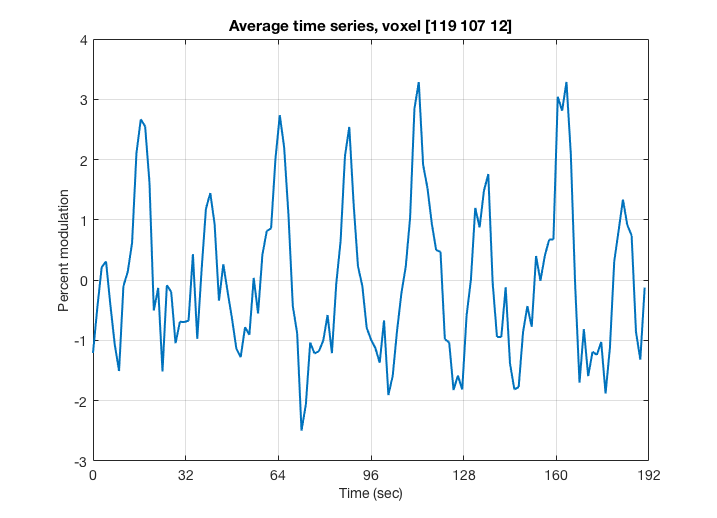

title('Average time series, voxel [119 107 12]')

% Notice that the average time series is cleaner than the time series from
% the three scans it was derived from

## Clean up

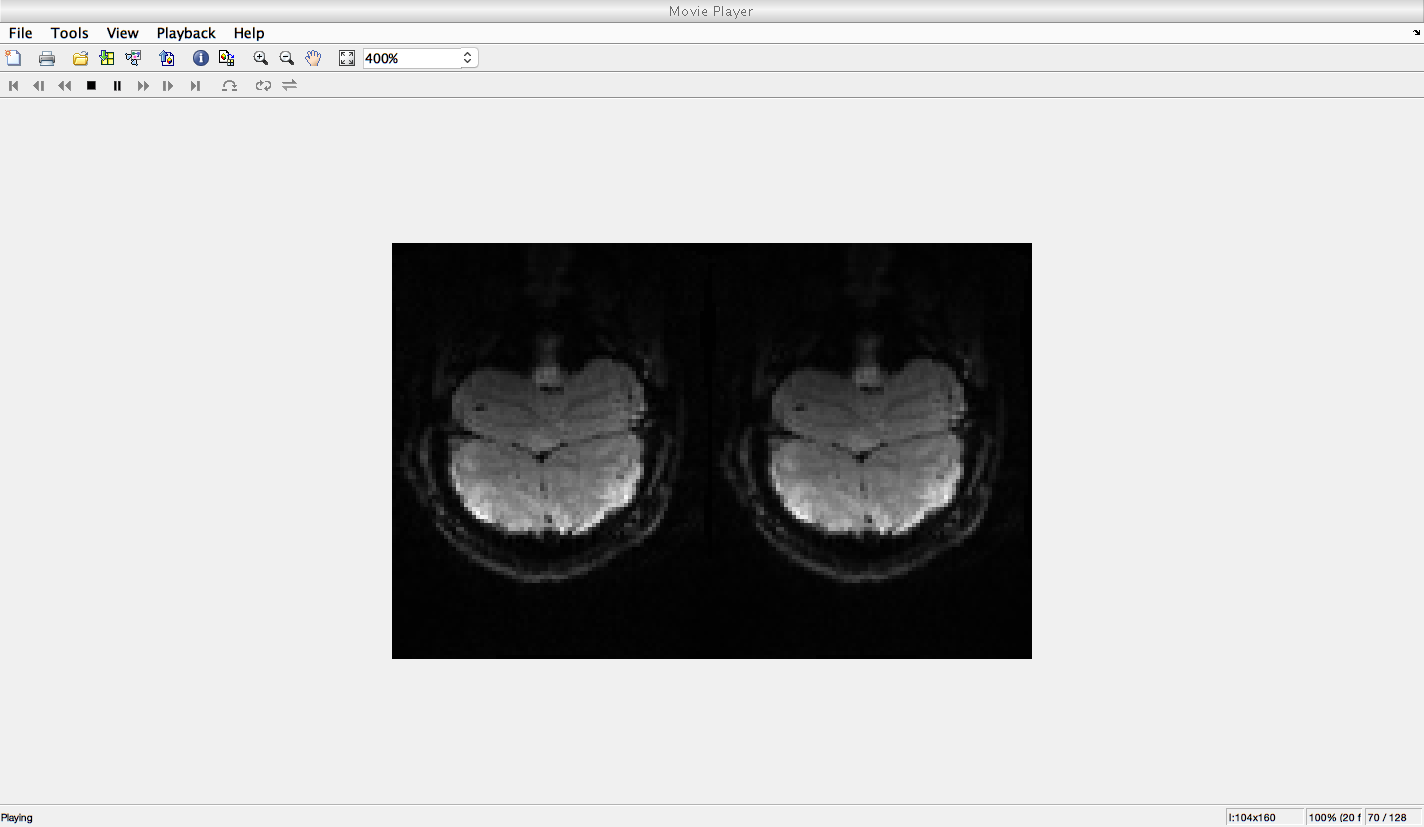

for ii = 1:length(fH)
    close(fH(ii));
end
mrvCleanWorkspace;